## **Load Data - Audiodatastore**

rng(1)

clear all
%clearvars sig

%datafolder = "C:\Users\hyosun\Documents\Research\Datasets\tau\tau\unzipped_tau\TAU-urban-acoustic-scenes-2020-mobile-development\data\TAU\audio_16k\"
datafolder = "hyosun/Downloads/audio_16k_20240911" 

datafolder = "hyosun/Downloads/audio_16k_20240911"

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','none'); %modified 'foldernames' into 'none' % 2024-09-06 Fri: label info is included in the file name, not in folder name as labels

Cannot find files or folders matching: 'hyosun/Downloads/audio_16k_20240911'.

## Convert data to 2D Scallogram

: Save a signal data to 2D scallogram image

% save Image to folder, and create the relevant subfolder
datafolder_scallogram = "hyosun/Documents/Research/Datasets/ESC50/images" %"C:\Users\bbeyes\Documents\TAU\images\"; %"images\"; 

datafolder_scallogram = "hyosun/Documents/Research/Datasets/ESC50/images"

- **Extract Label Information**

file_dir = split(ads.Files,"/") %ads.Files 

file_dir = 2000×6 cell array
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-100032-A-0.wav' }
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-100038-A-14.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-100210-A-36.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-100210-B-36.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-101296-A-19.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-101296-B-19.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-101336-A-30.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1-101404-A-34.wav'}
    {0×0 char}    {'Users'}    {'hyosun'}    {'Downloads'}    {'audio_16k_20240911'}    {'1

%file_dir{:,12}
file_name = file_dir(:,6)

file_name = 2000×1 cell array
    {'1-100032-A-0.wav' }
    {'1-100038-A-14.wav'}
    {'1-100210-A-36.wav'}
    {'1-100210-B-36.wav'}
    {'1-101296-A-19.wav'}
    {'1-101296-B-19.wav'}
    {'1-101336-A-30.wav'}
    {'1-101404-A-34.wav'}
    {'1-103298-A-9.wav' }
    {'1-103995-A-30.wav'}
    {'1-103999-A-30.wav'}
    {'1-104089-A-22.wav'}
    {'1-104089-B-22.wav'}
    {'1-105224-A-22.wav'}
    {'1-110389-A-0.wav' }
    {'1-110537-A-22.wav'}
    {'1-115521-A-19.wav'}
    {'1-115545-A-48.wav'}
    {'1-115545-B-48.wav'}
    {'1-115545-C-48.wav'}
    {'1-115546-A-48.wav'}
    {'1-115920-A-22.wav'}
    {'1-115920-B-22.wav'}
    {'1-115921-A-22.wav'}
    {'1-116765-A-41.wav'}
    {'1-11687-A-47.wav' }
    {'1-118206-A-31.wav'}
    {'1-118559-A-17.wav'}
    {'1-119125-A-45.wav'}
    {'1-121951-A-8.wav' }


%file_name(10)
file_name_split = split(file_name, ["-","."])

file_name_split = 2000×5 cell array
    {'1'}    {'100032'}    {'A'}    {'0' }    {'wav'}
    {'1'}    {'100038'}    {'A'}    {'14'}    {'wav'}
    {'1'}    {'100210'}    {'A'}    {'36'}    {'wav'}
    {'1'}    {'100210'}    {'B'}    {'36'}    {'wav'}
    {'1'}    {'101296'}    {'A'}    {'19'}    {'wav'}
    {'1'}    {'101296'}    {'B'}    {'19'}    {'wav'}
    {'1'}    {'101336'}    {'A'}    {'30'}    {'wav'}
    {'1'}    {'101404'}    {'A'}    {'34'}    {'wav'}
    {'1'}    {'103298'}    {'A'}    {'9' }    {'wav'}
    {'1'}    {'103995'}    {'A'}    {'30'}    {'wav'}
    {'1'}    {'103999'}    {'A'}    {'30'}    {'wav'}
    {'1'}    {'104089'}    {'A'}    {'22'}    {'wav'}
    {'1'}    {'104089'}    {'B'}    {'22'}    {'wav'}
    {'1'}    {'105224'}    {'A'}    {'22'}    {'wav'}
    {'1'}    {'110389'}    {'A'}    {'0' }    {'wav'}
    {'1'}    {'110537'}    {'A'}    {'22'}    {'wav'}
    {'1'}    {'115521'}    {'A'}    {'19'}    {'wav'}
    {'1'}    {'115545'}    {'A'}    {'48'}    

- **Save the labels**

labels = file_name_split(:,4)

labels = 2000×1 cell array
    {'0' }
    {'14'}
    {'36'}
    {'36'}
    {'19'}
    {'19'}
    {'30'}
    {'34'}
    {'9' }
    {'30'}
    {'30'}
    {'22'}
    {'22'}
    {'22'}
    {'0' }
    {'22'}
    {'19'}
    {'48'}
    {'48'}
    {'48'}
    {'48'}
    {'22'}
    {'22'}
    {'22'}
    {'41'}
    {'47'}
    {'31'}
    {'17'}
    {'45'}
    {'8' }


- **Create the folder name as labels**

%categorical(label)

%categories(categorical(label))

catego=categories(categorical(labels)); %categories(ads.Labels);
for i = 1:1:length(catego)
    imgLoc = fullfile(datafolder_scallogram,char(catego{i}));
    mkdir(imgLoc)
end

pwd

ans = '/Users'

- Example

length(ads.Files)

ans = 2000

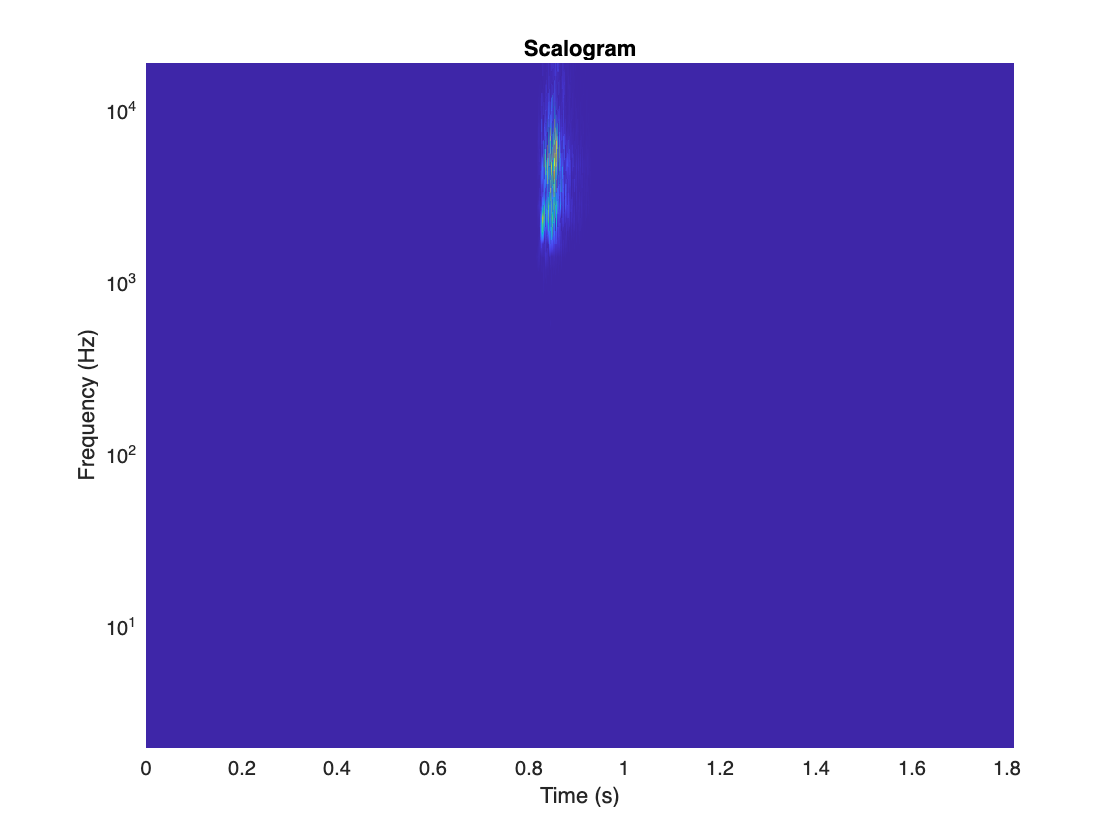

Fs = 44100;
sig = audioread(ads.Files{1});
fb = cwtfilterbank('SignalLength',length(sig),...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',4);
[cfs,frq] = wt(fb,sig);
t = (0:length(sig)-1)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

%helperCreateRGBfromTF(ads,datafolder_scallogram)

## 2 Data Preprocessing and Data Splitting **- added by CHS 2022-10-18 from Kevin Chng**

Audio properties that will require normalising

Following on from the previous notebook, we identifed the following audio properties that need preprocessing to ensure consistency across the whole dataset:

- Audio Channels

- Sample rate

- Bit-depth

We will continue to use Signal Processing Toolbox which will be useful for the pre-processing and feature extraction.

## **Sample rate conversion - added by CHS 2022-10-18 from Kevin Chng**

There is a wide range of Sample rates that have been used across all the samples which is a concern (ranging from 96k to 8k).

This likley means that we will have to apply a sample-rate conversion technique (either up-conversion or down-conversion) so we can see an agnostic representation of their waveform which will allow us to do a fair comparison

## Bit-depth **- added by CHS 2022-10-18 from Kevin Chng**

I resample the audio Wav. file to 16 bits. This removes the complication of the dataset having a wide range of bit-depths.

## **Merge audio channels - added by CHS 2022-10-18 from Kevin Chng**

We will also convert the signal to mono, meaning the number of channels will always be 1.

[It will take up to 30min for running, please be patient.]

%TODO Up convert or down convert
%From the information in the previous steps choose which what would you do?

for i=1:1:length(ads.Files)
    y =audioread(ads.Files{i});
    if size(y,2) == 1
        result = y;
    else
        result = (y(:,1)+y(:,2))/2;
    end
    audiowrite(ads.Files{i},result,44100,'BitsPerSample',16);
    clear y Fs result
end

**Save the images**

helperCreateRGBfromTF(ads,datafolder_scallogram, labels) % labels added

1-100032-A-0
1-100038-A-14
1-100210-A-36
1-100210-B-36
1-101296-A-19
1-101296-B-19
1-101336-A-30
1-101404-A-34
1-103298-A-9
1-103995-A-30
1-103999-A-30
1-104089-A-22
1-104089-B-22
1-105224-A-22
1-110389-A-0
1-110537-A-22
1-115521-A-19
1-115545-A-48
1-115545-B-48
1-115545-C-48
1-115546-A-48
1-115920-A-22
1-115920-B-22
1-115921-A-22
1-116765-A-41
1-11687-A-47
1-118206-A-31
1-118559-A-17
1-119125-A-45
1-121951-A-8
1-12653-A-15
1-12654-A-15
1-12654-B-15
1-13571-A-46
1-13572-A-46
1-13613-A-37
1-137-A-32
1-137296-A-16
1-14262-A-37
1-155858-A-25
1-155858-B-25
1-155858-C-25
1-155858-D-25
1-155858-E-25
1-155858-F-25
1-15689-A-4
1-15689-B-4
1-160563-A-48
1-160563-B-48
1-16568-A-3
1-16746-A-15
1-17092-A-27
1-17092-B-27
1-17124-A-43
1-17150-A-12
1-172649-A-40
1-172649-B-40
1-172649-C-40
1-172649-D-40
1-172649-E-40
1-172649-F-40
1-17295-A-29
1-17367-A-10
1-17565-A-12
1-17585-A-7
1-17742-A-12
1-17808-A-12
1-17808-B-12
1-1791-A-26
1-17970-A-4
1-18074-A-6
1-18074-B-6
1-181071-A-40
1-181071-B-40
1-1852

## Helper Function

function helperCreateRGBfromTF(ads,datafolder_scallogram, labels) % labels added 2024-09-06

    for i = 1:length(ads.Files)
        clearvars sig
        Fs = 44100;
        sig = audioread(ads.Files{i});
        %% CHS start ====
        %disp(sig)
        %% CHS end   ====
        fb = cwtfilterbank('SignalLength',length(sig),...
        'SamplingFrequency',Fs,...
        'VoicesPerOctave',4);
        cfs = abs(fb.wt(sig(:)));
        im = ind2rgb(im2uint8(rescale(cfs)),jet(128));   
        %imgLoc = fullfile(datafolder_scallogram,char(ads.Labels(i)));
        imgLoc = fullfile(datafolder_scallogram,char(labels(i)));
        
        [filepath,name,ext] = fileparts(ads.Files{i});
        disp(name);
        %name = strcat(name, ext);
        %disp({'file folder video name', name});
        
        %imFileName = strcat(char(ads.Labels(i)),'_',num2str(i),'.jpg');
        %imFileName = strcat(name, '_', char(ads.Labels(i)),'.jpg');
        imFileName = strcat(name, '_', char(labels(i)),'.jpg');
        imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
    end
end

% findLayersToReplace(lgraph) finds the single classification layer and the
% preceding learnable (fully connected or convolutional) layer of the layer
% graph lgraph.
function [learnableLayer,classLayer] = findLayersToReplace(lgraph)

    if ~isa(lgraph,'nnet.cnn.LayerGraph')
        error('Argument must be a LayerGraph object.')
    end
    
    % Get source, destination, and layer names.
    src = string(lgraph.Connections.Source);
    dst = string(lgraph.Connections.Destination);
    layerNames = string({lgraph.Layers.Name}');
    
    % Find the classification layer. The layer graph must have a single
    % classification layer.
    isClassificationLayer = arrayfun(@(l) ...
        (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
        lgraph.Layers);
    
    if sum(isClassificationLayer) ~= 1
        error('Layer graph must have a single classification layer.')
    end
    classLayer = lgraph.Layers(isClassificationLayer);
    
    
    % Traverse the layer graph in reverse starting from the classification
    % layer. If the network branches, throw an error.
    currentLayerIdx = find(isClassificationLayer);
    while true
        
        if numel(currentLayerIdx) ~= 1
            error('Layer graph must have a single learnable layer preceding the classification layer.')
        end
        
        currentLayerType = class(lgraph.Layers(currentLayerIdx));
        isLearnableLayer = ismember(currentLayerType, ...
            ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
        
        if isLearnableLayer
            learnableLayer =  lgraph.Layers(currentLayerIdx);
            return
        end
        
        currentDstIdx = find(layerNames(currentLayerIdx) == dst);
        currentLayerIdx = find(src(currentDstIdx) == layerNames);
        
    end
end